# Spectral Entropy DOA Analysis

## Load data

load case_1.mat

## 1) Plot `before` and `after`

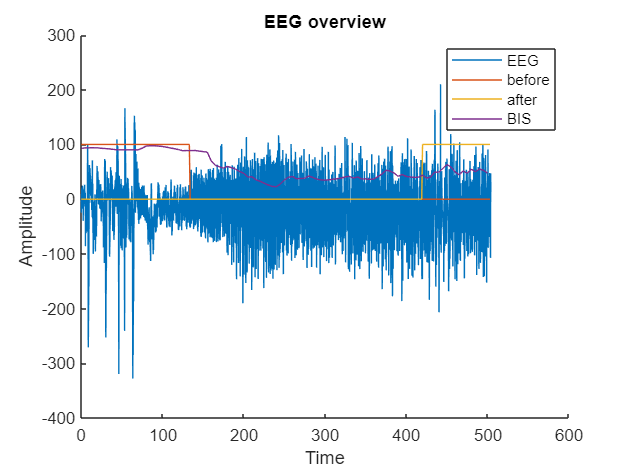

figure
hold on
plot(eeg_time,eeg_ch)
plot(annot_time,before * 100)
plot(annot_time,after * 100)
plot(bis_time,bis_ch)
legend('EEG','before', 'after', 'BIS')
xlabel('Time')
ylabel('Amplitude')
title('EEG overview')
hold off

It is hard to infer visually from the EEG whether a specific part belongs to awake or anesthesia period.

## 2) Sampling frequency of the EEG signal

Sampling rate could vary during the measurement process ? Yes

eeg_time_shift = zeros(length(eeg_time),1);
eeg_time_shift(2:end) = eeg_time(1:end-1);

fs_eeg_mean = round(1/mean(eeg_time - eeg_time_shift))

fs_eeg_mean = 128

fs_eeg = round(1 / (eeg_time(2) - eeg_time(1)))

fs_eeg = 125

## 3) Highpass filter design

### 3.1) FIR Filter

Using `designfilt`:

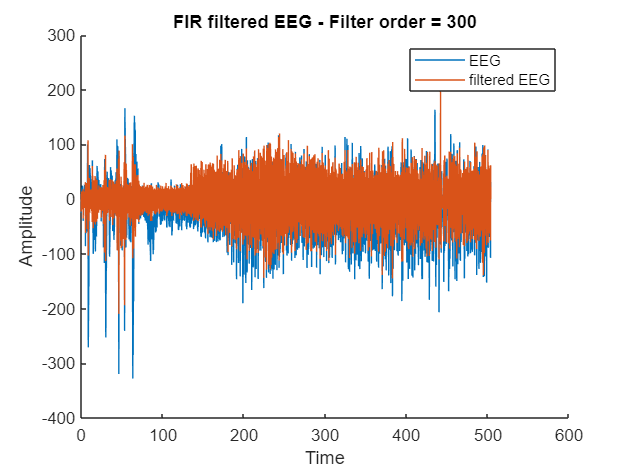

f_cutoff = 0.5;
w0 = f_cutoff/(fs_eeg/2);

hpf_fir = designfilt('highpassfir','CutoffFrequency',f_cutoff,'StopbandAttenuation',55,'FilterOrder',300,'SampleRate',fs_eeg);
% fvtool(hpf_fir);
eeg_f = filtfilt(hpf_fir,eeg_ch);
figure
hold on
plot(eeg_time,eeg_ch)
plot(eeg_time, eeg_f)
legend('EEG','filtered EEG')
xlabel('Time')
ylabel('Amplitude')
title('FIR filtered EEG - Filter order = 300')
hold off

Using `highpass`:

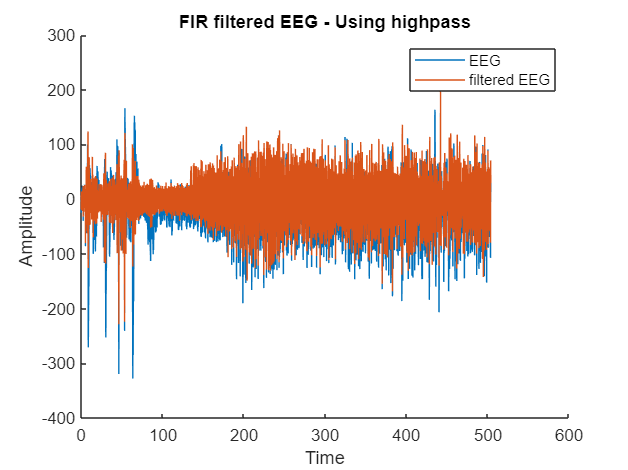

[eeg_f,d] = highpass(eeg_ch,f_cutoff,fs_eeg);
figure
hold on
plot(eeg_time,eeg_ch)
plot(eeg_time, eeg_f)
legend('EEG','filtered EEG')
xlabel('Time')
ylabel('Amplitude')
title('FIR filtered EEG - Using highpass')
hold off

### 3.2) IIR Filter

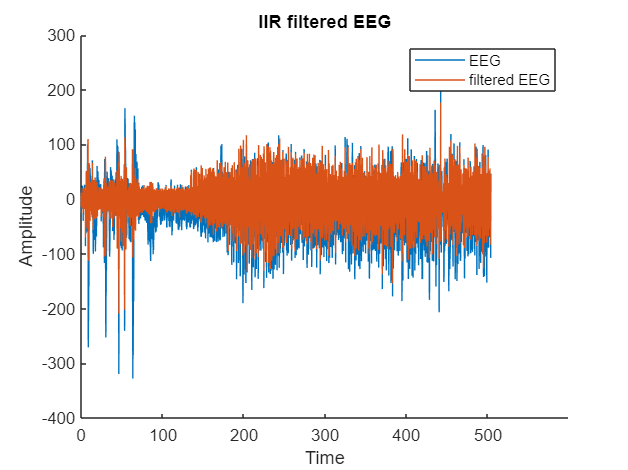

hpf_iir = designfilt('highpassiir', ...
    'PassbandFrequency',f_cutoff, ...
    'StopbandAttenuation',55, ...
    'FilterOrder',4, ...
    'SampleRate',fs_eeg, ...
    'PassbandRipple',1);
% fvtool(hpf_fir);
eeg_f = filtfilt(hpf_iir,eeg_ch);
figure
hold on
plot(eeg_time,eeg_ch)
plot(eeg_time, eeg_f)
legend('EEG','filtered EEG')
xlabel('Time')
ylabel('Amplitude')
title('IIR filtered EEG')
hold off

## 4)  Plot & comment

Plotting has been done in Part 3.

The filtering made the most effect on the begining of the anaesthetic delivery.

## 5) Spectral Entropy DOA

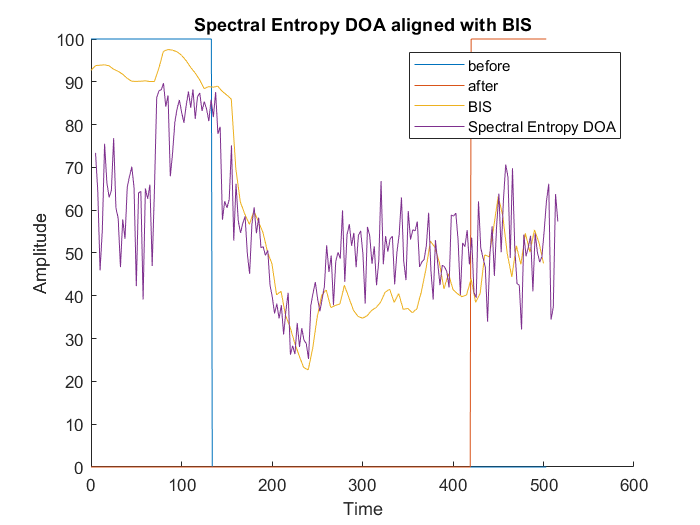

[H, t_H] = entropy_eeg(eeg_f, fs_eeg);
figure
hold on
plot(annot_time,before * 100)
plot(annot_time,after * 100)
plot(bis_time,bis_ch)
plot(t_H, H * 100);
legend('before', 'after', 'BIS','Spectral Entropy DOA')
xlabel('Time')
ylabel('Amplitude')
title('Spectral Entropy DOA aligned with BIS')
hold off

## Extra: Investigate phase shift

fvtool(hpf_fir,'Analysis','freq');